#### Víctor Asanza, Rebeca Estrada, Danny Torres, Steven Santillan and Juan Cadena

- `More examples: https://github.com/vasanza/Matlab_Code`

- `Read more: https://vasanza.blogspot.com/`

# Initialization

clear;clc;
path = fullfile('./Data/agriculture.mat');
Datos=load(path);Datos=Datos.Datos;
nDatos=(Datos./max(Datos));

addpath(genpath('./src'))%functions folders
% inputs: Item, air humidity, air temperature, soil moisture, light and rain
input=nDatos(1:length(nDatos)-1,2:6);
% output: soil moisture in the following time step
output=nDatos(2:length(nDatos),4);

# Data Visualization

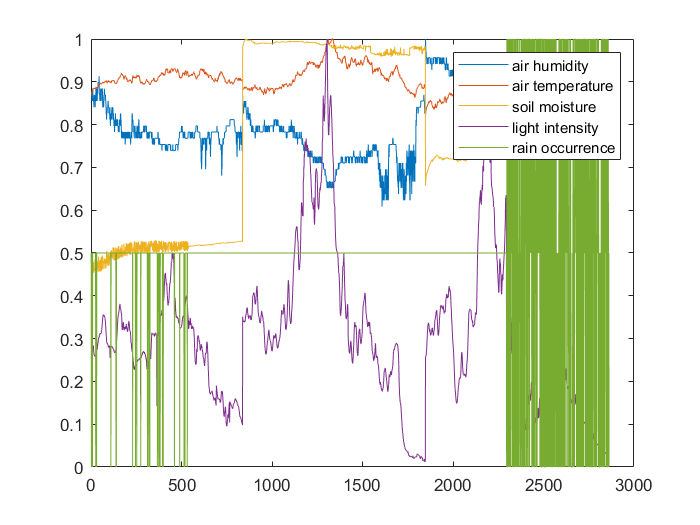

plot(input)
legend('air humidity', 'air temperature', 'soil moisture', 'light intensity', 'rain occurrence');

# Testing NN as Regression (Bayesian Regularization)

yest = myNeuralNetworkFunction_BR(input)

yest =     0.4481
    0.4544
    0.4475
    0.5074
    0.4640
    0.4579
    0.4605
    0.4649
    0.4628
    0.4613


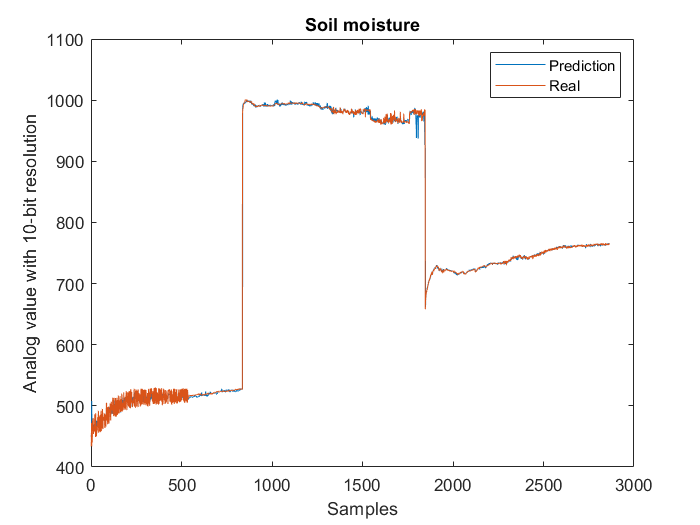

figure
plot(yest*max(Datos(:,4)))
hold on
plot(output*max(Datos(:,4)))
title("Soil moisture");legend("Prediction","Real");
xlabel("Samples");ylabel("Analog value with 10-bit resolution");

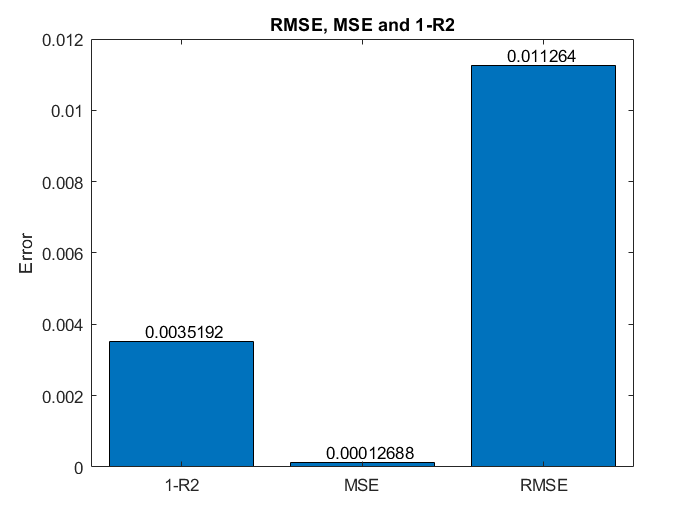

rmse = 0.0113

mse = 1.2688e-04

r2 = 0.9965


[rmse,mse,r2] = fBar_RmseMseR2(yest,output)

# Testing NN as Regression (Levenberg-Marquardt)

yest = myNeuralNetworkFunction_LM(input)

yest =     0.4472
    0.4561
    0.4571
    0.4466
    0.4623
    0.4558
    0.4581
    0.4651
    0.4585
    0.4601


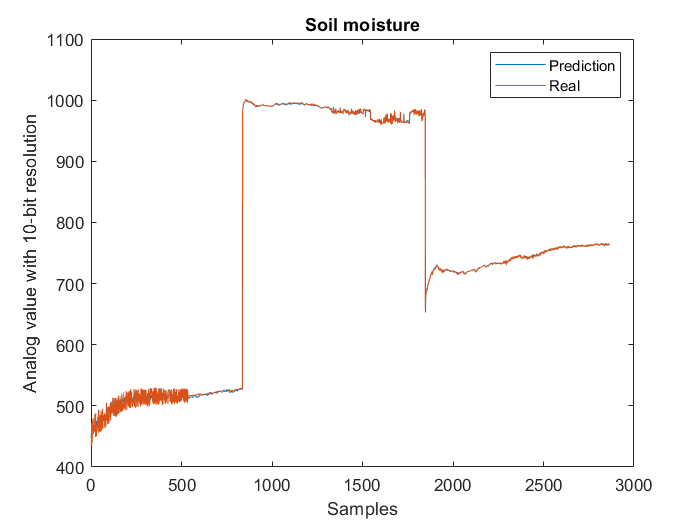

figure
plot(yest*max(Datos(:,4)))
hold on
plot(output*max(Datos(:,4)))
title("Soil moisture");legend("Prediction","Real");
xlabel("Samples");ylabel("Analog value with 10-bit resolution");

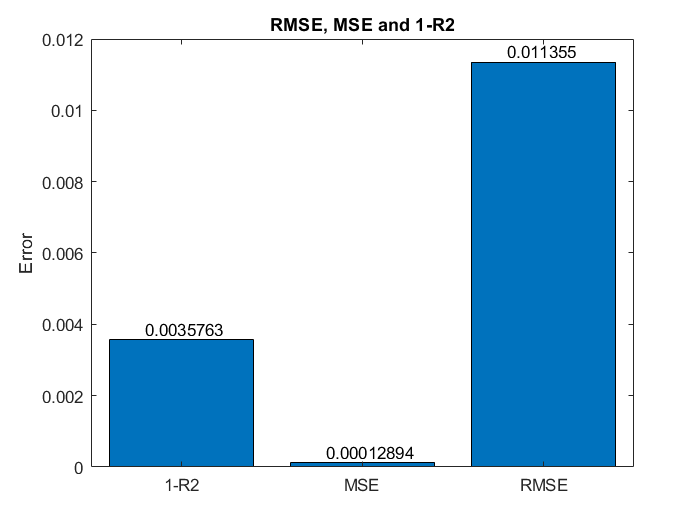

rmse = 0.0114

mse = 1.2894e-04

r2 = 0.9964


[rmse,mse,r2] = fBar_RmseMseR2(yest,output)